# MATLAB教程_week3

## 一. 图形对象

    图形对象是用来创建可视化数据的组件。每个对象在图形显示中都具有特定角色。例如，一个线图包含一个图窗对象、一个坐标区对象和一个图形线条对象。可以通过设置它们的属性来自定义图形对象。 要设置属性，可以通过创建该对象的函数将其以输出参数的形式返回。例如，`plot` 函数返回图形线条对象。然后，使用圆点表示法查看和设置属性，或者使用get()和set()函数查看和设置属性。

### 1. Line属性

x = 0:0.1:10;
y = x.^2;
p = plot(x, y);
get(p)

    AlignVertexCenters: off
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: off
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: on
                 Color: [0 0.4470 0.7410]
             ColorMode: 'auto'
           ContextMenu: [0×0 GraphicsPlaceholder]
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: on
         Interruptible: on
              LineJoin: 'round'
             LineStyle: '-'
         LineStyleMode: 'auto'
             LineWidth: 0.5000
                Marker: 'none'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1×101 uint64]
            MarkerMode: 'auto'
            MarkerSize: 6
                Parent: [1×1 Axes]
         PickableParts: 'visible'
    

    可使用 get() 函数查询特定属性：

get(p, 'LineStyle')

ans = '-'

    可用原点表示法修改设置属性

p.LineWidth = 3

p =   Line - 属性:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  显示 所有属性


    也可用 set() 函数设置属性

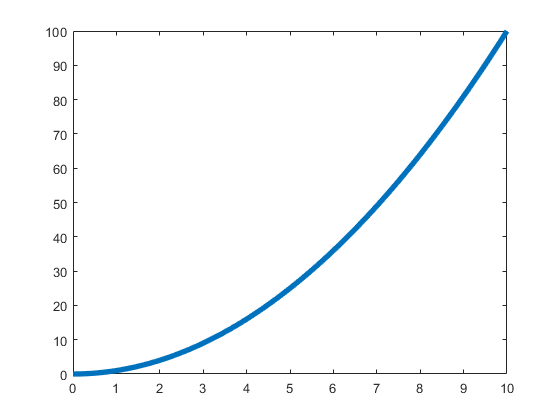

set(p, 'LineWidth', 4)

还可以在创建对象时使用名称-值对组参数设置属性。例如

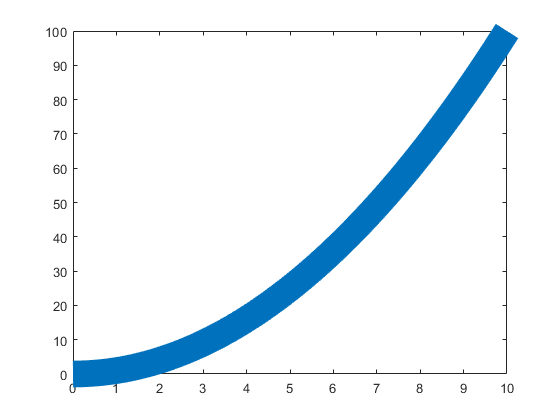

plot(x, y, 'LineWidth', 20);

    作业中可能用到更多属性，请参阅matlab官方文档。

#### 2. Axes属性

`    Axes` 属性控制 `Axes` 对象的外观和行为。通过更改属性值，您可以修改坐标区的特定方面。使用圆点表示法查询和设置属性。

ax = gca % get current axes

ax =   Axes - 属性:

             XLim: [0 10]
             YLim: [0 100]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  显示 所有属性


ax.Color = 'yellow';
ax.XLim = [1 9];     % 修改坐标轴范围

    可以更改 Axes 属性给绘图增加标签

ax.Title.String = 'My Title';
ax.Title.FontSize = 20;
ax.XLabel.String = 'My x-Axis Label';
ax.YLabel.String = 'My y-Axis Label';

    也可以直接使用函数添加标签

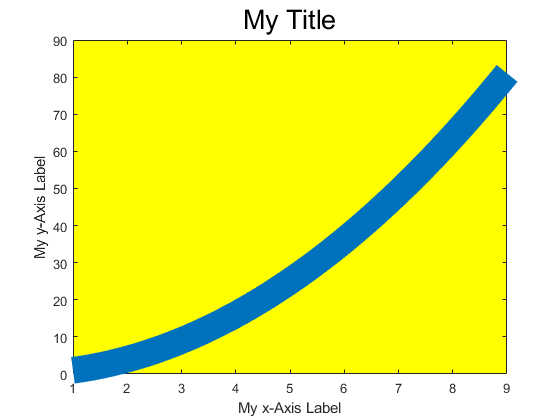

title('My Title', 'FontSize', 20);
xlabel('My x-Axis Label');
ylabel('My y-Axis Label');

    作业中可能用到更多属性，请参阅matlab官方文档。

## 二. 优化问题初步

    安装 Optimization Toolbox，在实时脚本中，选择**插入——任务——优化**或者**实时编辑器——任务——优化。**

    下面给出一个求解有约束非线性问题的示例：

    问题为在单位圆盘上最小化 Rosenbrock 函数`f``(``x,y``)=100(y−``x``^2)^2+(1−``x``)^2，约束条件为x^2+y^2<=1。`

    首先执行下面一行代码把初值写入工作区。

x0 = [0;0]; % 迭代初始点(x, y) = (0, 0)

    下面使用求解器求解该问题，结果放入 solution 和 objectiveValue 变量中。对于不同的问题，可参照文档末尾的 objectiveFcn 和 unitdisk 函数自行修改。

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.000000e+00    0.000e+00    2.000e+00
    1      13    7.753537e-01    0.000e+00    6.250e+00    1.768e-01
    2      18    6.519648e-01    0.000e+00    9.048e+00    1.679e-01
    3      21    5.543209e-01    0.000e+00    8.033e+00    1.203e-01
    4      24    2.985207e-01    0.000e+00    1.790e+00    9.328e-02
    5      27    2.653799e-01    0.000e+00    2.788e+00    5.723e-02
    6      30    1.897216e-01    0.000e+00    2.311e+00    1.147e-01
    7      33    1.513701e-01    0.000e+00    9.706e-01    5.764e-02
    8      36    1.153330e-01    0.000e+00    1.127e+00    8.169e-02
    9      39    1.198058e-01    0.000e+00    1.000e-01    1.522e-02
   10      42    8.910052e-02    0.000e+00    8.378e-01    8.301e-02
   11      45    6.771960e-02    0.000e+00    1.365e+00    7.149e-02
   12      48    6.437664e-02    0.000e+00    1

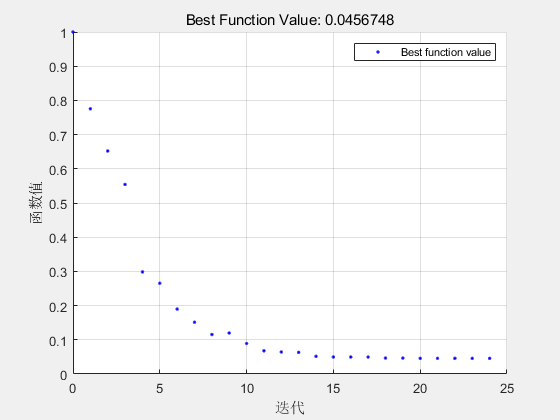


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% 设置非默认求解器选项
options = optimoptions('fmincon','Display','iter','PlotFcn',...
    'optimplotfvalconstr');

% 求解
[solution,objectiveValue] = fmincon(@objectiveFcn,x0,[],[],[],[],[],[],...
    @unitdisk,options);


% 清除变量
clearvars options

使用disp函数查看运行结果：

disp(solution)

    0.7864
    0.6177



disp(objectiveValue)

    0.0457



## 三. 矩阵可视化

### 1. meshgrid函数

meshgrid函数可用于创建二维表格

x = 1:3;
y = 1:5;
[X,Y] = meshgrid(x,y)

X =      1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3


Y =      1     1     1
     2     2     2
     3     3     3
     4     4     4
     5     5     5


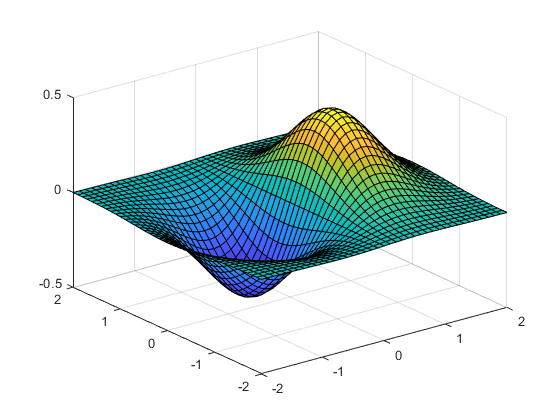

x = -2:0.1:2;
y = x;
[X,Y] = meshgrid(x);
F = X.*exp(-X.^2-Y.^2);
surf(X,Y,F)

### 2. 使用contour函数绘制等高线

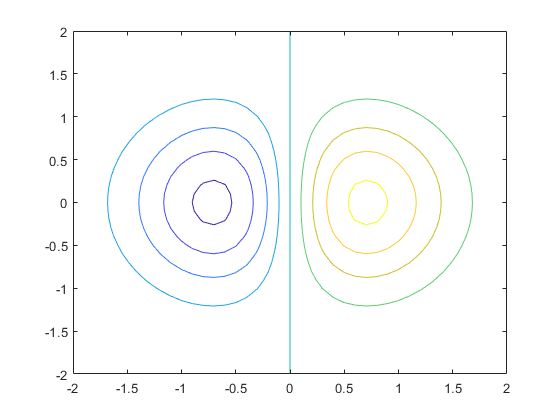

contour(X, Y, F);

### 3. 使用streamline函数绘制流线

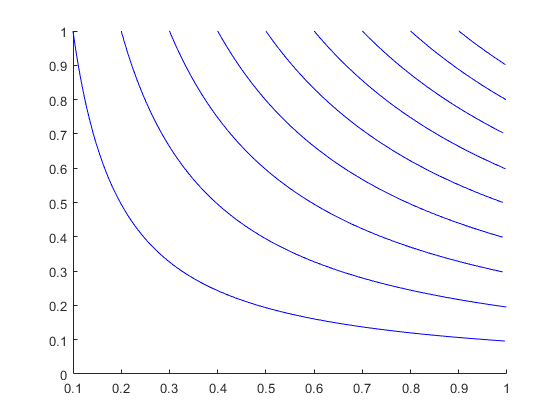

[x,y] = meshgrid(0:0.1:1,0:0.1:1);
u = x;    % x方向速度
v = -y;   % y方向速度
startx = 0.1:0.1:1;  % x起始点
starty = ones(size(startx));  % y起始点
figure;
streamline(x,y,u,v,startx,starty);

function f = objectiveFcn(optimInput)
% 示例:
% 最小化 Rosenbrock 函数
% f = 100*(y - x^2)^2 + (1 - x)^2

% 编辑以下行以添加您的计算方法
x = optimInput(1);
y = optimInput(2);
f = 100*(y - x^2)^2 + (1 - x)^2;
end

function [c,ceq] = unitdisk(x)
% 示例：
% 单位圆盘

% 编辑以下行以添加您的计算方法
% 注意，如果没有不等式约束，请指定 c = []
% 注意，如果没有等式约束，请指定 ceq = []
c = x(1)^2 + x(2)^2 - 1;
ceq = [ ];
end